# FFT_25.mlx

**This file ...**

Imports data directly from Excel spreadsheet. 

The data is imported as a dataTable and must be converted to data (numbers).

The data for each column may then be specified. 

The first column is time, the second column is swPCD voltage amplitude

% Specify the path, the Excel file name and tab name
excelFile = 'C:\Users\2923821P\Dropbox\PhD\ENG5316 Advanced Ultrasonics\Coursework\Data\Horn data_25.xlsx';
sheetName = 'Horn data_25%';
dataTable = readtable (excelFile, 'Sheet', 'Horn data_25%');

% Extract data from the table
data = table2array(dataTable); % Convert table to array

% Convert data to double (assuming the data is numeric)
data = double(data);

% Assuming the data file has two columns: time and amplitude
time = data(:, 1);
amplitude_raw = data(:, 2);

# Prepare the data for the FFT

- Determine the sampling frequency.

- Remove the DC offset

- Create a new vector with the DC offset removed.

- Apply a window function (Hamming)

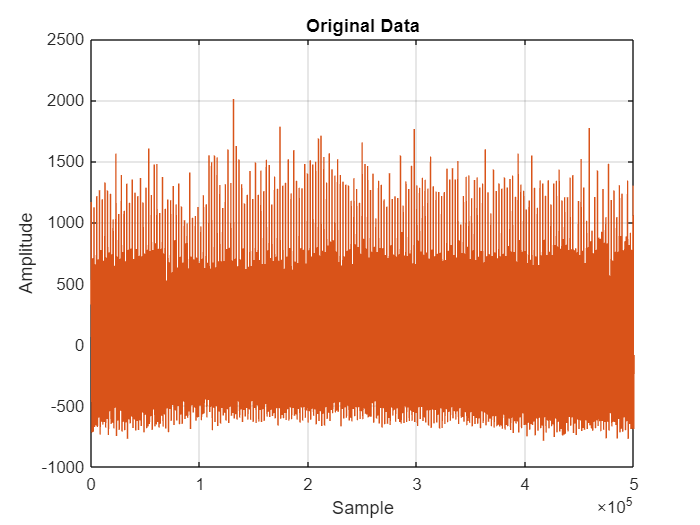

% Sampling frequency
fs = 1 / (time(2) - time(1));

% Calculate the number of samples 
N = height(amplitude_raw);

% Calculate DC offset (mean value)
dc_offset = mean(amplitude_raw);

% Remove DC offset
amplitude_offset_free_data = amplitude_raw - dc_offset;

% Apply Hamming window
window = hamming(height(amplitude_offset_free_data));  % Generate Hamming window of the same length as data
data_windowed = amplitude_offset_free_data .* window;  % Combine data with the window.

% Plot original data
plot(data);
title('Original Data');
xlabel('Sample');
ylabel('Amplitude');
grid on;

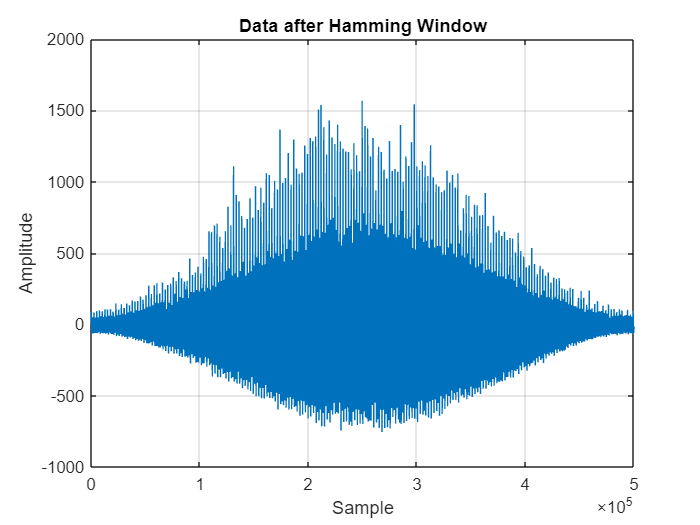

% Plot the windowed data
plot(data_windowed);
title('Data after Hamming Window');
xlabel('Sample');
ylabel('Amplitude');
grid on;

## Plot the windowed FFT data

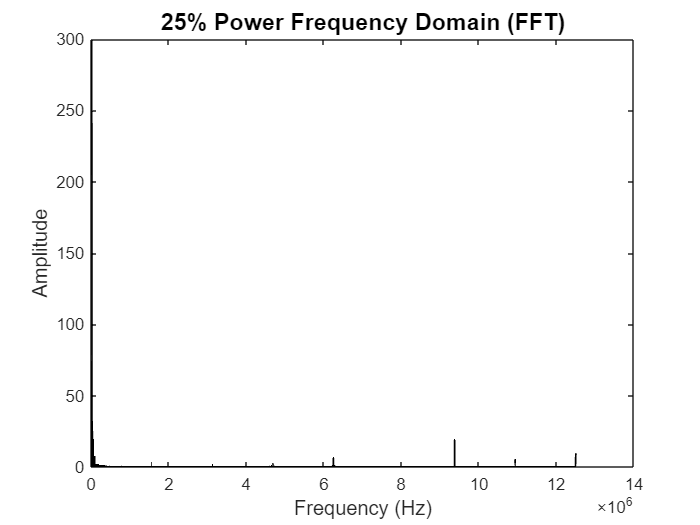

% FFT Result
fft_result = fft(data_windowed);
frequencies = fs * (0:(N/2))/N;

% Plot frequency spectrum
%subplot(1,1,1);
plot(frequencies, 2/N * abs(fft_result(1:floor(N/2) + 1)), 'Linewidth', 1, 'Color', 'black');
title('25% Power Frequency Domain (FFT)', 'FontSize', 14);
xlabel('Frequency (Hz)', FontSize = 12);
ylabel('Amplitude', FontSize=12);


%xlim([0 14000000])
%ylim([0 600])

## Apply a 30kHz High-Pass filter

Fpass = 30000; % Passband frequency (Hz)
Fstop = 20000; % Stopband frequency (Hz)
Rp = 1; % Passband ripple (dB)
Astop = 60; % Stopband attenuation (dB)
hp_filter = designfilt('highpassiir', 'PassbandFrequency', Fpass, ...
    'StopbandFrequency', Fstop, 'PassbandRipple', Rp, 'StopbandAttenuation', Astop, ...
    'SampleRate', fs, 'DesignMethod', 'butter');
% Apply high-pass filter
data_filtered = filtfilt(hp_filter, data_windowed);


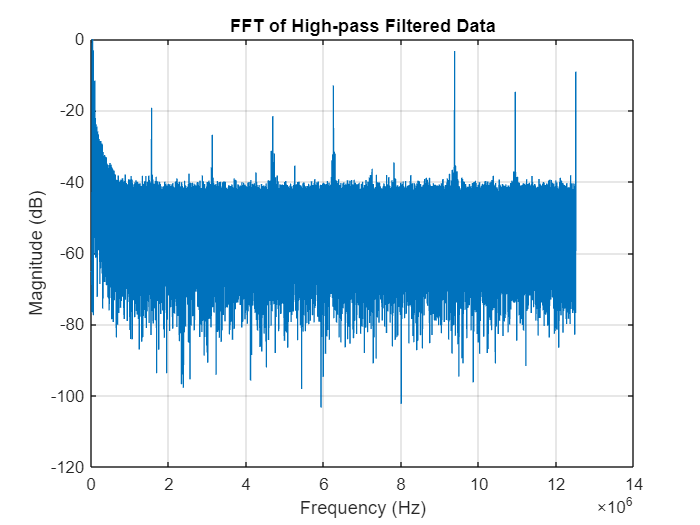

% Perform FFT
Y = fft(data_filtered);
frequencies = fs * (0:(N/2))/N;
Y_mag = abs(Y(1:N/2+1)); % Magnitude of FFT
Y_mag_normalized = Y_mag / max(Y_mag); % Normalize magnitude

% Plot FFT results
figure;
plot(frequencies, 20*log10(Y_mag_normalized)); % Plot in dB scale
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('FFT of High-pass Filtered Data');
grid on;

% Display peak frequency
[~, idx] = max(2/N * abs(Y_mag(1:N/2 + 1)));
disp(['Peak frequency: ', num2str(frequencies(idx)), ' Hz']);

Peak frequency: 39700 Hz
